# Computing controllers that ensure a phase margin of 60 degrees

### Compute and declare my transfer function

The transfer function has the following form:


$$H_f \left(s\right)=\frac{K_f }{s\left(T_f s+1\right)}$$


Knowing that my values are Kf = 4 and  Tf = 8, the function becomes:


$$H_f \left(s\right)=\frac{4}{s\left(8s+1\right)}$$


I declare my transfer function in code:

Kf = 4;
Tf = 8;
Hf = tf(Kf,[Tf 1 0])

Hf =
 
      4
  ---------
  8 s^2 + s
 
Continuous-time transfer function.



Declare the phase margin's value

gammaK = 60;

## Computing a PD

phaseHol = -180 + gammaK;

We choose $\beta$ between 0.1 and 0.125

beta = 0.1;

phaseHc = atand((1-beta)/2/sqrt(beta));

phaseHp = phaseHol - phaseHc;

I get the value of $w_c$ from bode:

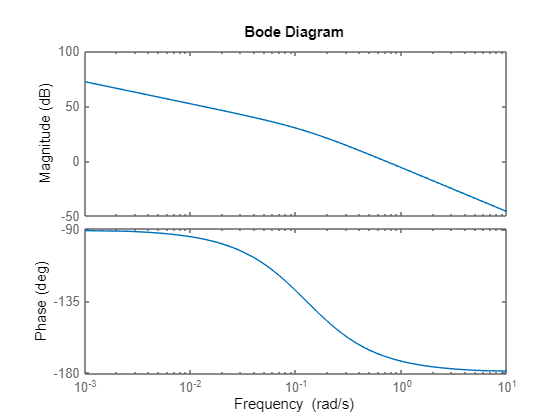

bode(Hf)

Wc = 1.4;

td = 1/Wc/sqrt(beta);

I read the value of  $|H_p \left(jw_c \right)|$ from Bode

magHp = 10^((-12)/20);

kp = sqrt(beta)/magHp;

Using PD general formula, I compute the final open loop transfer function.

Hpd = Hf*kp*tf([td 1],[beta*td 1])

Hpd =
 
       11.37 s + 5.036
  -------------------------
  1.807 s^3 + 8.226 s^2 + s
 
Continuous-time transfer function.



% bode(Hpd)

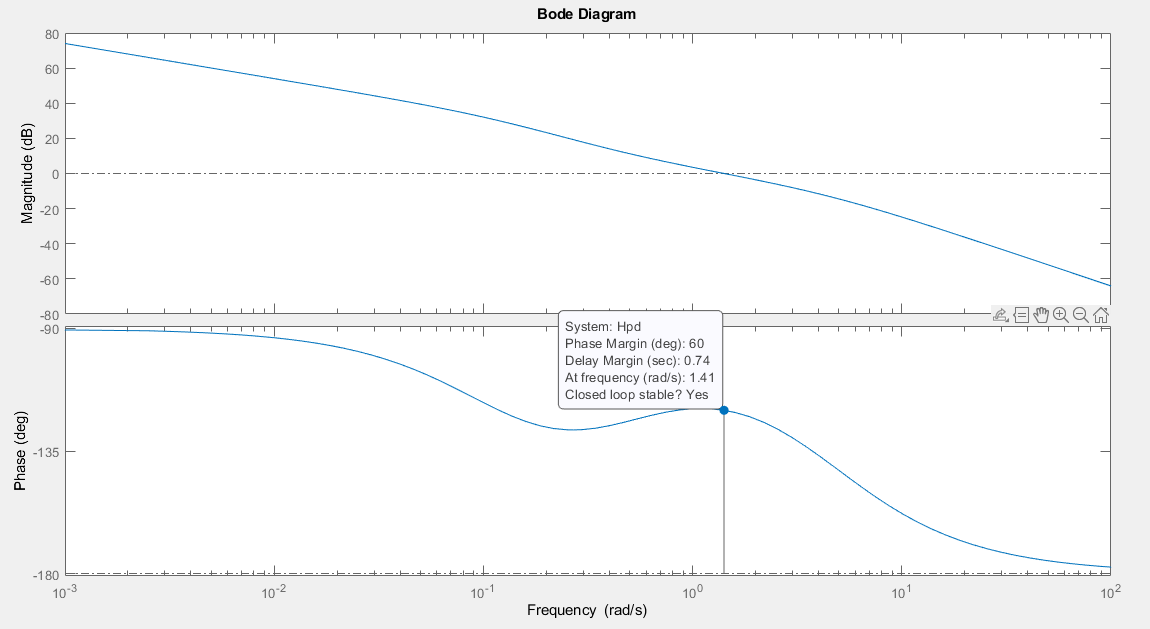

## Computing a PI

phaseHol = -180 + gammaK;

phaseHc = -15;

phaseHp = phaseHol - phaseHc;

I get the value of $w_c$ from bode:

bode(Hf)

Wc = 0.035;

Ti = 4/Wc;

I read the value of  $|H_p \left(jw_c \right)|$ from Bode

magHp = 10^(40/20);

kp = 1/magHp;

Using PI general formula, I compute the final open loop transfer function.

Hpi = Hf*kp*tf([Ti 1],[Ti 0])

Hpi =
 
     4.571 s + 0.04
  ---------------------
  914.3 s^3 + 114.3 s^2
 
Continuous-time transfer function.



% bode(Hpi)